## Parkinson's Disease Demographics Report

%The purpose of this file is to upload and reorganize an excel sheet with patient info to then look for relationships between variables. 

Demographics of study participants in McKay et al., 2021

Background

We recently showed that sensorimotor control of balance was abnormal in individuals with Parkinson's disease (PD) compared to matched individuals. In particular, we found that a parameter of the so-called "Sensorimotor Response Model" (SRM) was able to differentiate PD from controls. However, no attempt was made to perform analyses of associations across the multiple SRM parameters; therefore the full picture of how balance is affected in PD is unknown.

### Objective

%(Use heading 2 instead of bolding for sections of the paper)

Summarize demographics of pariticipants with PD in McKay et al., 2021.

Perform a discriminant analysis (or similar) to identify patterns of abnormal sensorimotor feedback associated with PD.

#### Data sources

All data were taken from McKay et al., 20201; all data of participants with PD were used. No exclusions were applied.

A sample of source data is shown below

%Begin by importing the data needed
warning("off")
DATA = readtable('S1.csv');

head(DATA(1:5,1:6))

ans = 5×6 table
     Patient      Age       Sex        StudyGroup    PDDuration     TAka 
    __________    ___    __________    __________    __________    ______

    {'bat001'}    84     {'Female'}      {'PD'}          17        8.2803
    {'bat002'}    53     {'Male'  }      {'PD'}           4        7.2872
    {'bat003'}    75     {'Female'}      {'PD'}           2        8.0683
    {'bat007'}    59     {'Male'  }      {'PD'}           6        1.4374
    {'bat008'}    71     {'Female'}      {'PD'}           3        5.8099



%Convert DATA to string
%----------------------------------------------------------------------------------------------------------------------------


### Methods

All data were taken from McKay et al., 20201; all data of participants with PD were used. No exclusions were applied.

#### Statistical analyses

All statistical tests were performed in Matlab r2020a at alpha = 0.05. All hypothesis tests were performed two-sided.

### Results

TK

%DATA
% Look at the fourth column, there are multiple groups here. Let's focus only on those with PD, 
% to do this click on the downward pointing triangle next to "StudyGroup" 
% and then deselect every box except for PD. 

% New code should have appeared under the table that looks like this
% DATA = DATA(strcmp(DATA.StudyGroup,'PD'),:)
% Let's save this new table so we are only looking at PD participants, 
% save as DATA2 (don't forget to suppress the output by using a semicolon

DATA2 = DATA(strcmp(DATA.StudyGroup,'PD'),:); %Lucas does not recommend using this
%summary(DATA2)
class(DATA2.StudyGroup);
DATA2.StudyGroup = string(DATA2.StudyGroup);
Names = DATA2.Properties.VariableNames;


DATAage = DATA2(:,'Age');
DATAsex = DATA2(:,"Sex");
DATAduration = DATA2(:, "pd_duration");
DATAgains = DATA2(:,{'TAka','TAkv', 'TAkd', 'TAlambda', 'TAkaPrime',...
    'TAkvPrime', 'TAkdPrime', 'TAlambdaPrime', 'TAkaAg', 'TAkvAg', ...
    'TAkdAg','TAlambdaAg','MGka','MGkv','MGkd','MGlambda', ...
    'MGkaPrime','MGkvPrime','MGkdPrime','MGlambdaPrime', ...
    'MGkaAg','MGkvAg','MGkdAg','MGlambdaAg'});
DATAscores = DATA2(:, {'num_falls_6_mo','mds_updrs_iii_3a',	'mds_updrs_iii_3b',...
    'mds_updrs_iii_3c',	'mds_updrs_iii_3d',	'mds_updrs_iii_3e', 'updrs_iii_22_neck',...
    'updrs_iii_22_rue',	'updrs_iii_22_lue',	'updrs_iii_22_rle',	'updrs_iii_22_lle' });
DATAhy = DATA2(:,'hy');
DATAmoca = DATA2(:,"moca_total");

DATA3 = [DATAage DATAsex DATAduration DATAhy DATAgains DATAmoca DATAscores];

%DATA3.num_falls_6_mo(isnan(DATA3.num_falls_6_mo)) = 0; %Check assumption
%DATAscores(isnan(DATAscores)) = 0;
DATA3.Sex = categorical(DATA3.Sex);


## Single value for rigidity score

%Make a new column of neck rigidity scores, equal to the scoring that isn't
%NA

[m,n] = size(DATA3);
Neck_Rigidity = zeros(m,1);
Rue_Rigidity = zeros(m,1);
Lue_Rigidity = zeros(m,1);
Rle_Rigidity = zeros(m,1);
Lle_Rigidity = zeros(m,1);

TTTa = string(DATA3.mds_updrs_iii_3a);
TTTb = string(DATA3.mds_updrs_iii_3b);
TTTc = string(DATA3.mds_updrs_iii_3c);
TTTd = string(DATA3.mds_updrs_iii_3d);
TTTe = string(DATA3.mds_updrs_iii_3e);

for i = 1:m
    if strcmp(string(TTTa(i)), 'NA')
        Neck_Rigidity(i,1) = str2double(DATA3.updrs_iii_22_neck(i));
    else 
        Neck_Rigidity(i,1) = str2double(DATA3.mds_updrs_iii_3a(i));
    end
    
    
    if strcmp(string(TTTb(i)), 'NA')
        Rue_Rigidity(i,1) = str2double(DATA3.updrs_iii_22_rue(i));
    else 
        Rue_Rigidity(i,1) = str2double(DATA3.mds_updrs_iii_3b(i));
    end   
    
    
    if strcmp(string(TTTc(i)), 'NA')
        Lue_Rigidity(i,1) = str2double(DATA3.updrs_iii_22_lue(i));
    else 
        Lue_Rigidity(i,1) = str2double(DATA3.mds_updrs_iii_3c(i));
    end 
    
    
    if strcmp(string(TTTd(i)), 'NA')
        Rle_Rigidity(i,1) = str2double(DATA3.updrs_iii_22_rle(i));
    else 
        Rle_Rigidity(i,1) = str2double(DATA3.mds_updrs_iii_3d(i));
    end 
    
    
    if strcmp(string(TTTe(i)), 'NA')
        Lle_Rigidity(i,1) = str2double(DATA3.updrs_iii_22_lle(i));
    else 
        Lle_Rigidity(i,1) = str2double(DATA3.mds_updrs_iii_3e(i));
    end 
end

DATAScores2 = table(Neck_Rigidity, Rue_Rigidity, Lue_Rigidity, Rle_Rigidity, Lle_Rigidity);
DATA4 = [DATA3 DATAScores2];

### Table 1

Age = mn_sd_str(DATA4.Age);
Female = sex_categorical_str(DATA4.Sex);
Duration = mn_sd_str(DATA4.pd_duration);
Falls = mn_sd_str(DATA4.num_falls_6_mo);
Demo = ["Age (years)" "Sex (F/M)" "PD Duration (months)" "Falls"]';
Value = [Age Female Duration Falls]';
table(Demo,Value)

ans = 4×2 table
             Demo              Value 
    ______________________    _______

    "Age (years)"             "68±7" 
    "Sex (F/M)"               "21/23"
    "PD Duration (months)"    "7±5"  
    "Falls"                   "6±28" 


# Figure 1

A histogram of the PD participants age. The age range from 65 to 75 represents the most participants. 

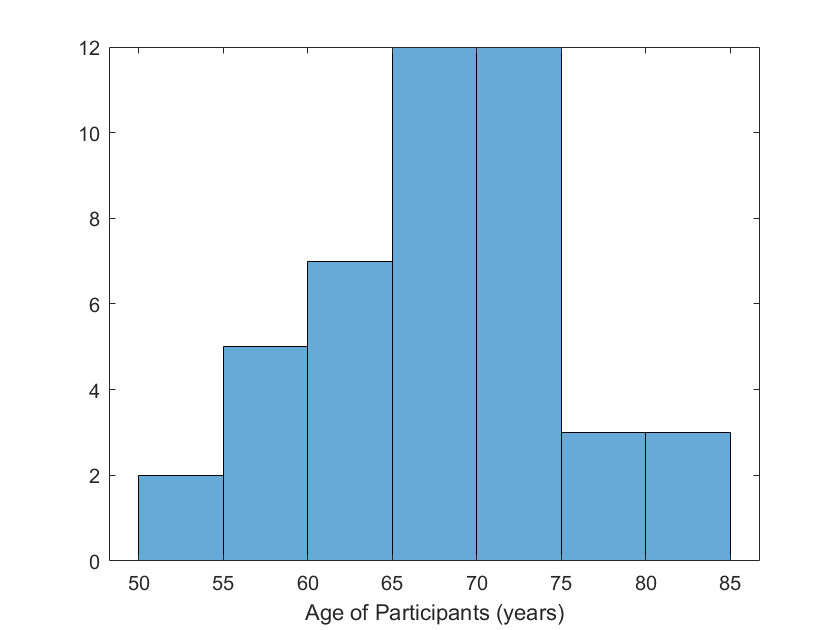

DATAdemo = DATA2(:,[1:3,5,34]); %Matrix with Pt identifier, age, sex, PD duration, and MoCA score
DATAdemo.Sex = categorical(DATAdemo.Sex);
CountSex = countcats(DATAdemo.Sex);

figure(1)
histogram(DATAdemo.Age)
xlabel("Age of Participants (years)");

# Figure 2

Histogram of PD duration, most participants have had PD for 10 months or less

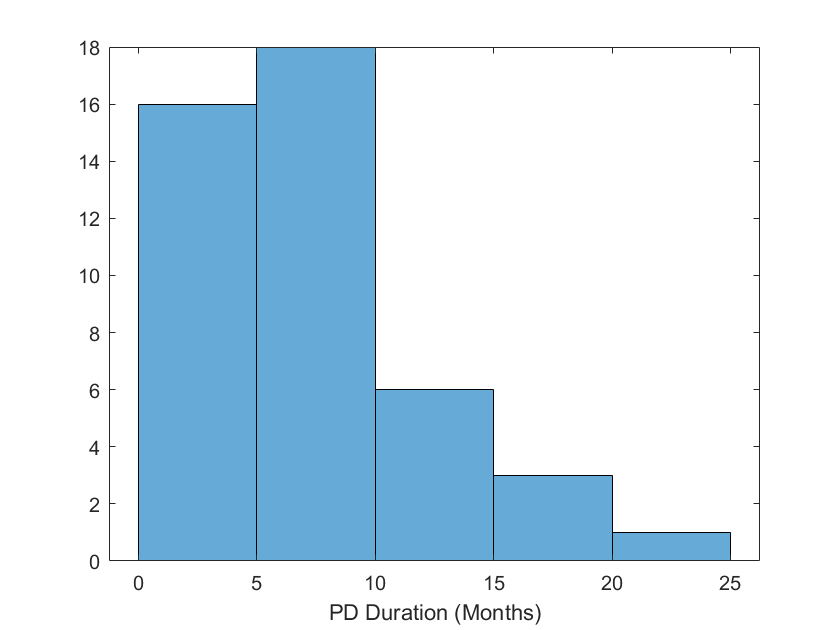

figure(2)
histogram(DATA4.pd_duration)
xlabel("PD Duration (Months)");

# Figure 3

Total Montreal Cognitive Assessment (MoCA) score. 

The maximum possible score is 30, with a score of 26 and above considered normal. 

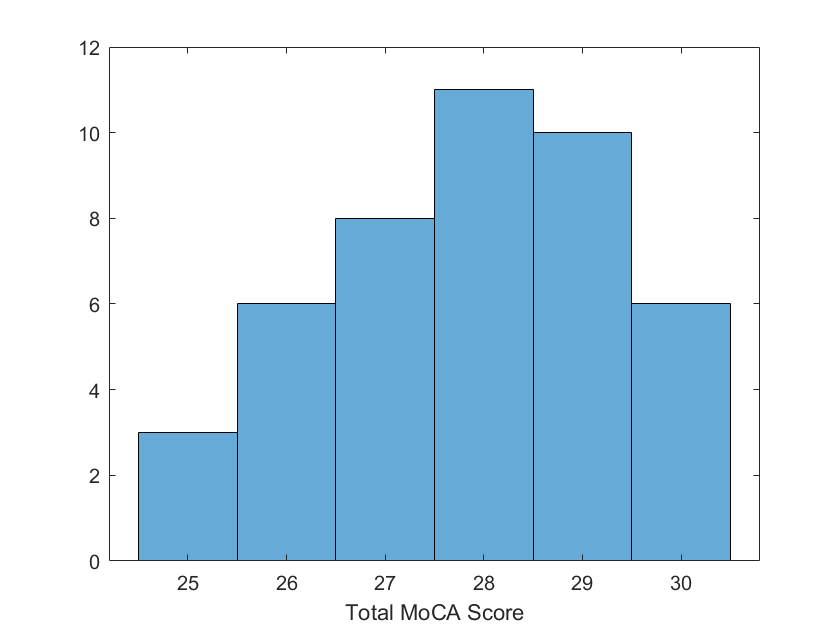

figure(3)
histogram(DATA4.moca_total)
xlabel("Total MoCA Score");

# Figure 4

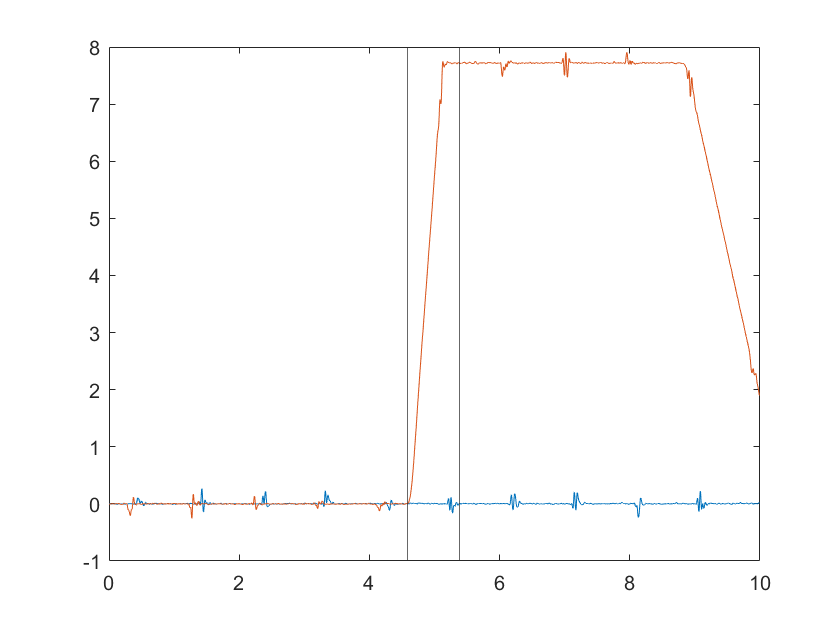

clf
figure(4)
load("Trial02.mat")
 
T = atime;
Pos = data.analog.platemotion(:,2);
Vel = data.analog.platemotion(:,4);
Acc = data.analog.platemotion(:,6);
Start = platStart(Acc);
End = Start + 799;
plot(T, LVDT)
hold on
xline(T(Start))

xline(T(End))

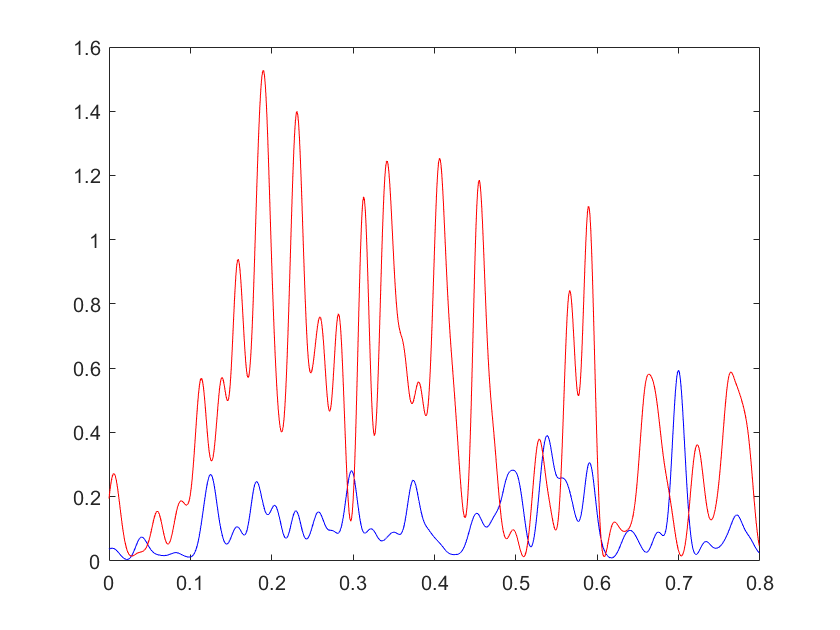

figure(6)
Tplat = T(Start:End) - T(Start);
plot(Tplat, EMG(Start:End,3),'b') %MG-L
hold on
%plot(Tplat, EMG(Start:End,4),'b') %MG-R
plot(Tplat, EMG(Start:End,7),'r') %TA-L

%plot(Tplat, EMG(Start:End,8),'r') %TA-R


### Discussion

TK